Ejercicio 1:

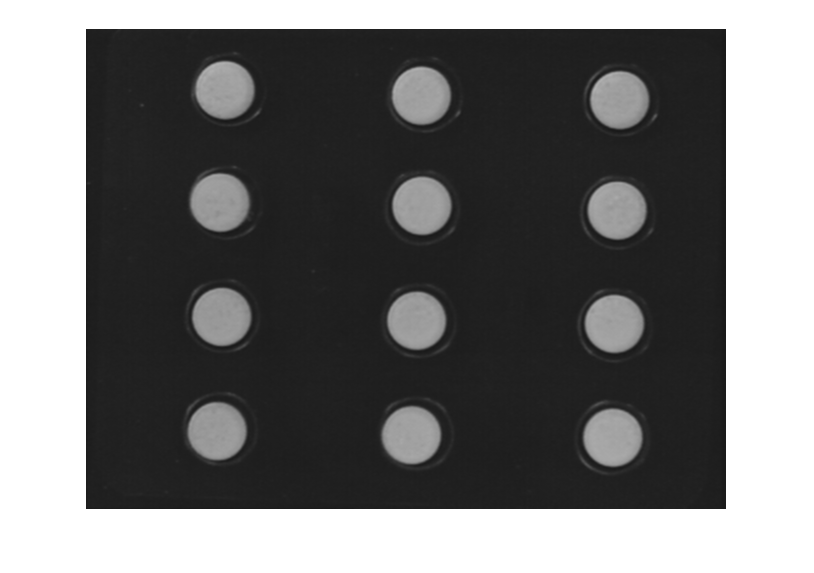

I = imread('Blispac1.tif');
I = rgb2gray(I);
imshow(I);

Para binarizar las pastillas, hemos calculado la cantidad de pixeles que ocupan las mismas. De este modo, mediante la funcion ejercicio1 obtenemos el valor sobre el que debemos binarizar la imagen para separar el valor de la escala de grises correspondiente al porcentaje de pixeles (alpha) que le hemos indicado.

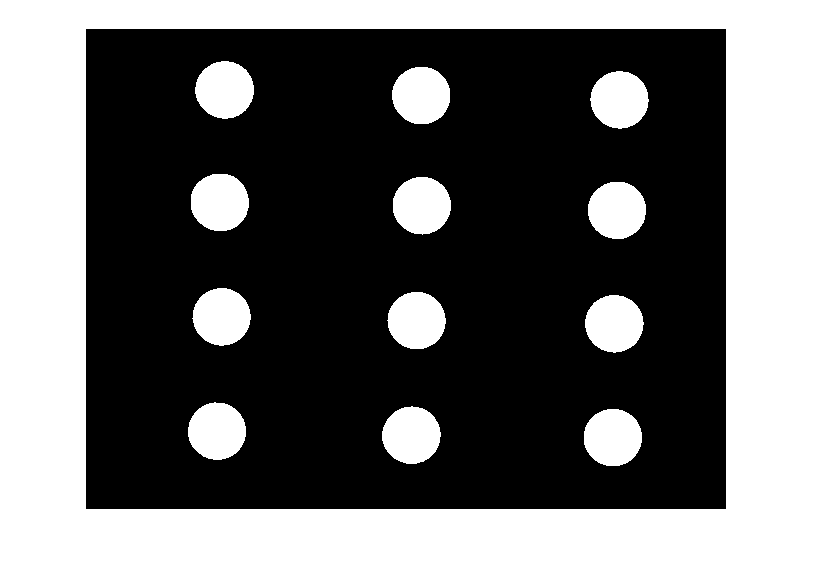

alpha = (12*pi*29^2) / (size(I,1)*size(I,2));
bin_level = exercici1(I, alpha);
I = I > bin_level;
imshow(I);

Ejercicio 2:

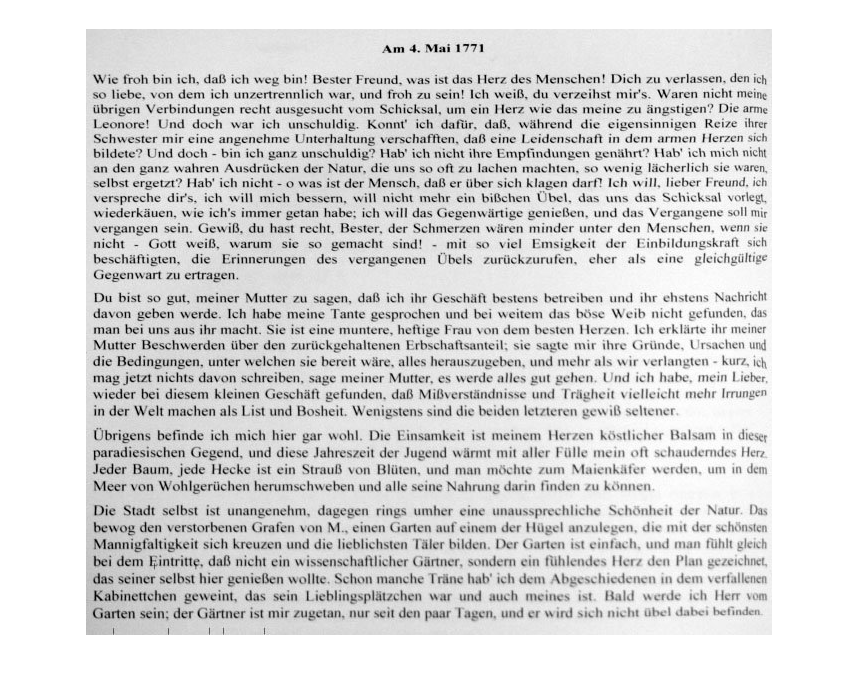

I = imread('ocr.png');
I = rgb2gray(I);
imshow(I);

M=3;
N=10;
F = colfilt(I, [N M], 'sliding', @exercici2);

Utilizando una ventana de 10x3, con un valor de K = 9, obtenemos la siguiente binarizacion del texto anterior:

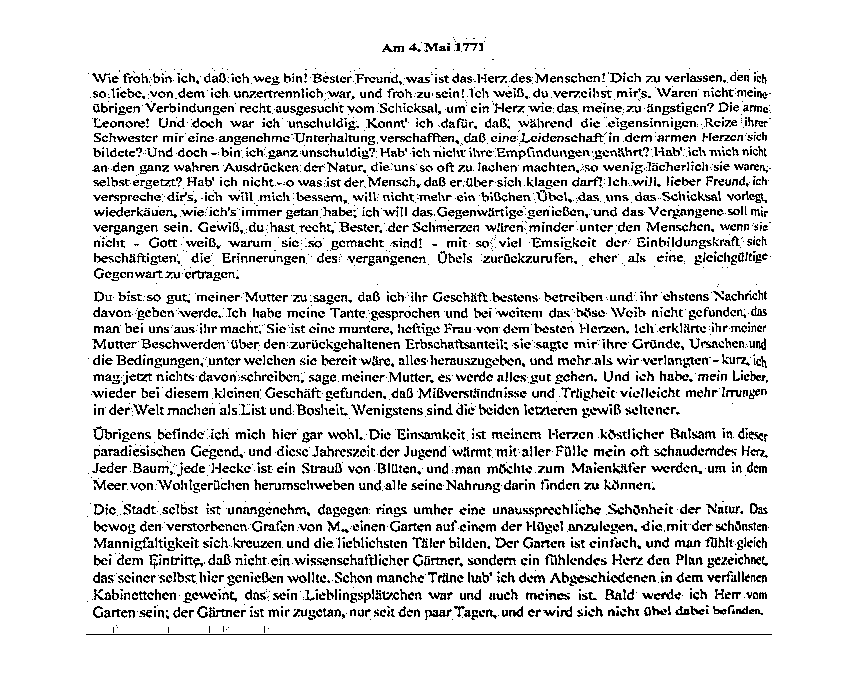

imshow(F);

Exercici 3:

En este apartado debemos segmentar la imagen en 4 elementos segun su color utilizando el algoritmo de clustering kmeans:

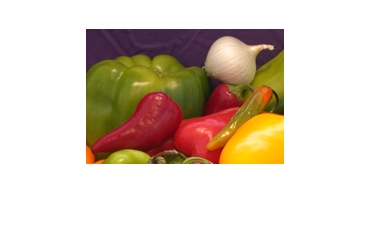

I = imread('onion.png');
imshow(I);

Los resultados son los siguientes:

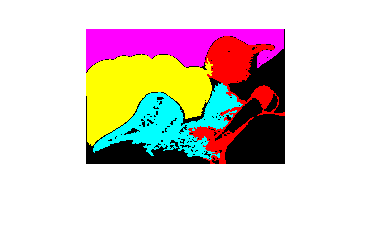

RGB = exercici3(I);
imshow(RGB, []);